# Homework 6

## 1.

%load('face.mat');
X=reshape(Y,[10304,33]).';
disp(size(X));

          33       10304



### 1(a).

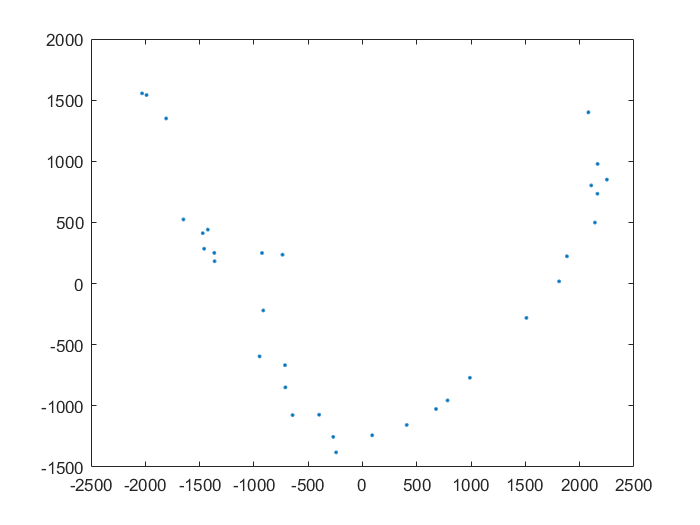

X=double(X);
[y,e] = cmdscale(dist(X.'), 2);
plot(y(:,1),y(:,2),'.')

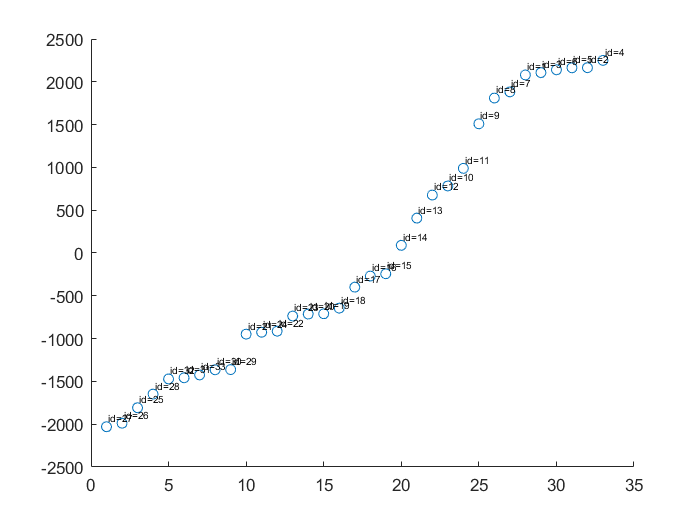

x = linspace(1,33,33);
[y_sorted, y_order] = sort(y(:,1));
id_new = id(y_order);
scatter(x,y_sorted(:,1));

for t = 1:numel(x)
  text(x(t)+0.1,y_sorted(t)+100,sprintf('id=%d',id_new(t)),'FontSize',6)
end

### 1(b).

D=dist(X.'); 
%[Y_iso, R_iso, E_iso] = isomapII(D, 'k', 5); 

### 1(c).

[Y_lle] = lle(X.',5,2);

LLE running on 33 points in 10304 dimensions
-->Finding 5 nearest neighbours.
-->Solving for reconstruction weights.
-->Computing embedding.


Done.


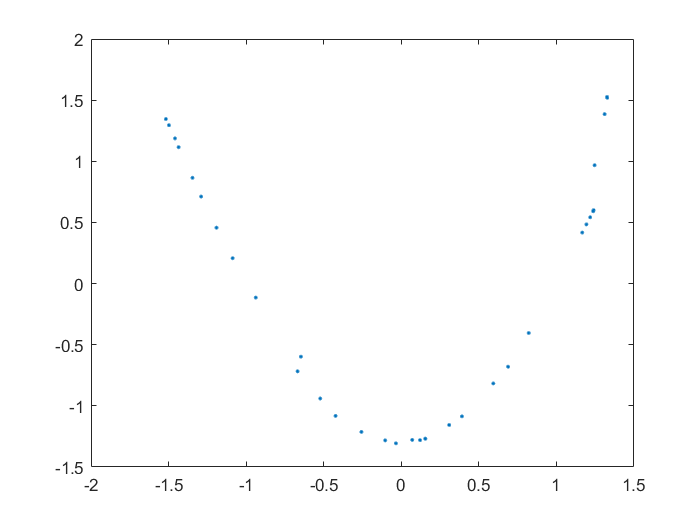

plot(Y_lle(1,:),Y_lle(2,:),'.')

## 2.

 Swiss roll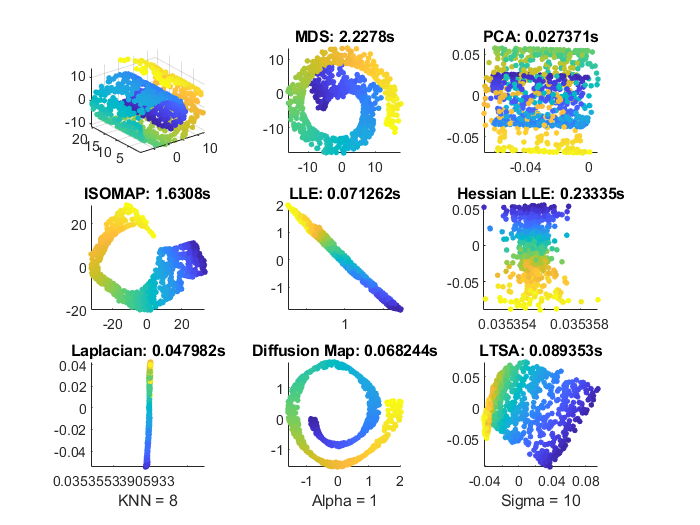

Swiss hole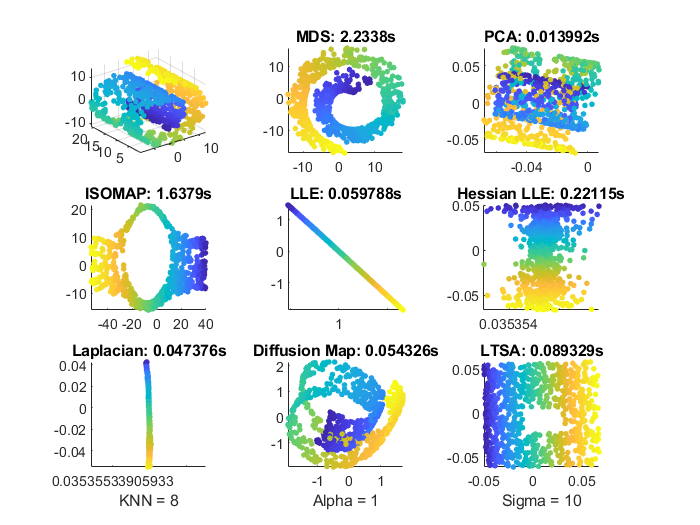

Corner Planes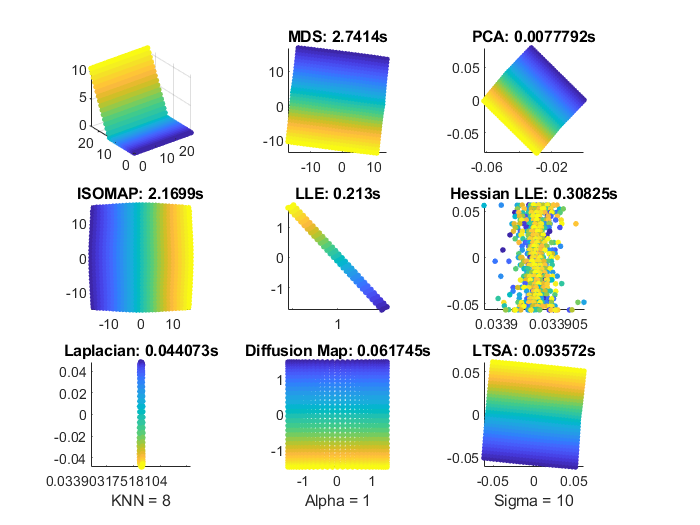

Punctured Sphere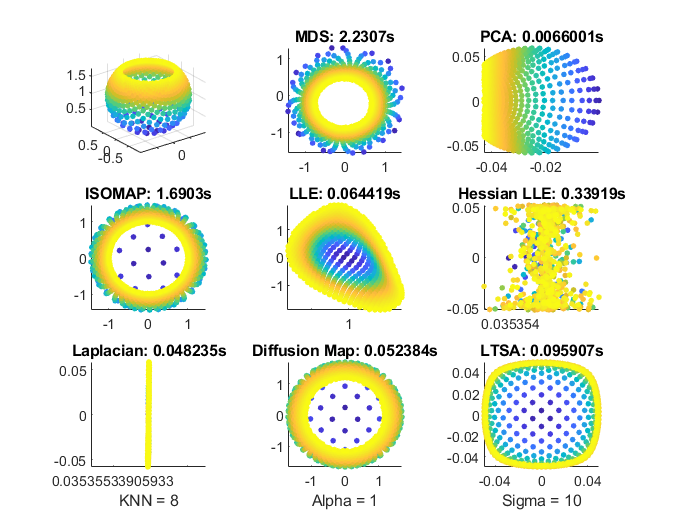

Twin Peaks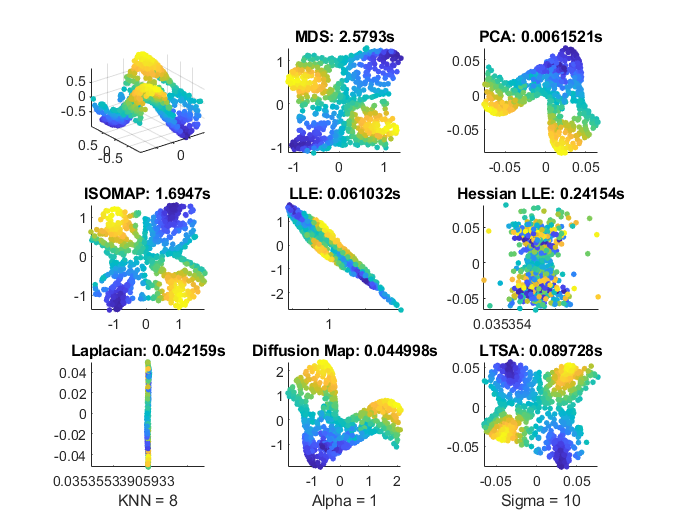

3D Clusters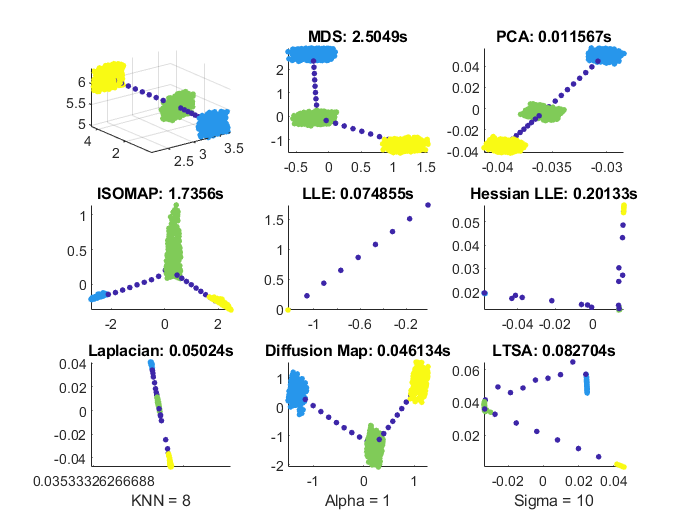

Toroidal Helix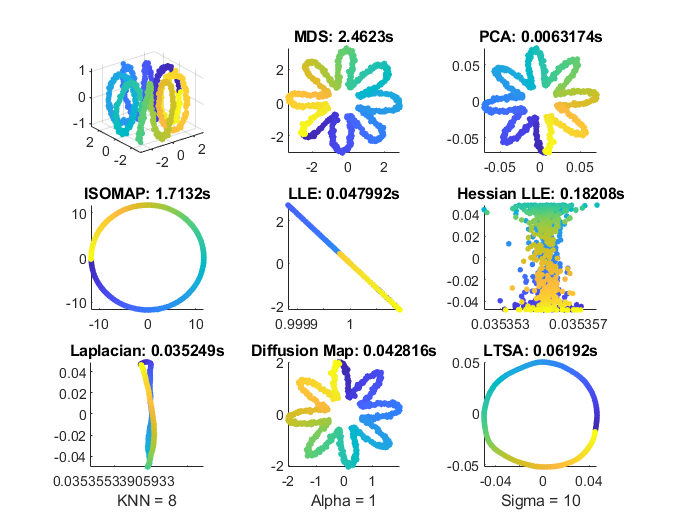

Gaussian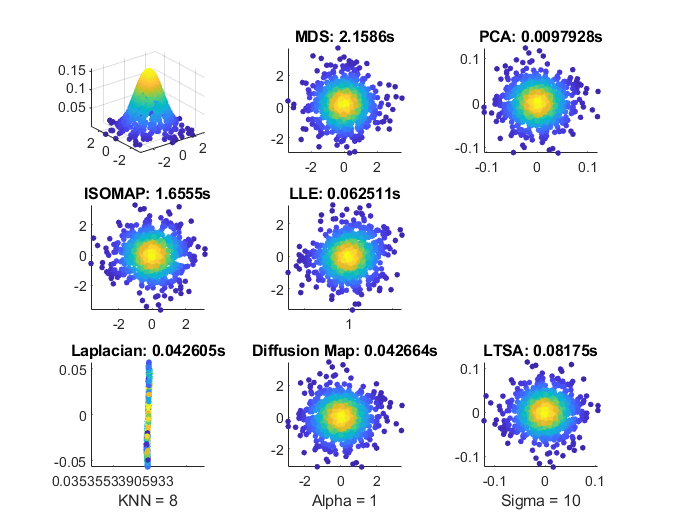

Occluded Disks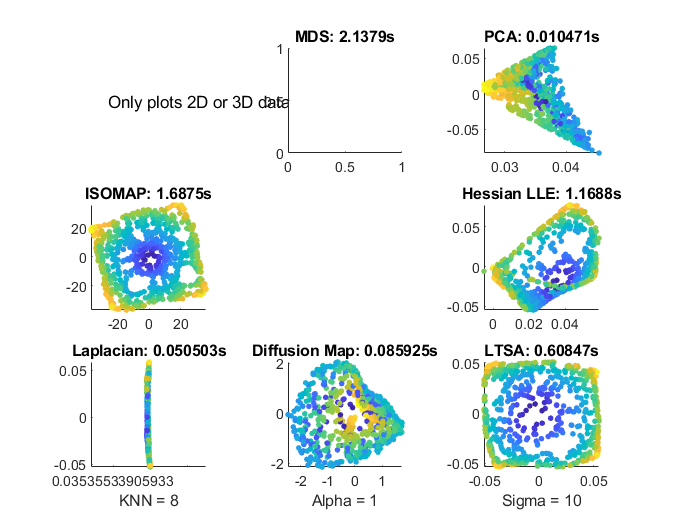

For the examples and methods here, PCA is the fastest method among all the 8 methods while MDS is the lowest one. Laplacian method always make all the things into one line so the visualization is not good. PCA and Difusion map usually keep the shape of the 3D data and MDS and ISOMAP sometimes do that. LLE mehods always give simple but clear visualization of manifold learning results.